# 8. Modelo Gaométrico Inverso

1. Determine el modelo geométrico inverso del robot asignado haciendo uso de la metodología explicada en clase. 

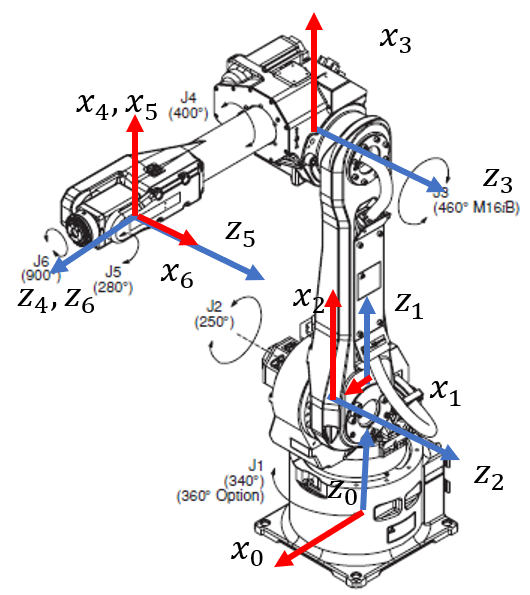

Debido a que es un robot de 6 GDL, es necesario solucionar la cinemática inversa con desacople cinemático. Con esto la posición de la intersección de los últimos tres ejes está determinada solo por la configuración de las tres primeras articulaciones, mientras que la orientación por las últimas tres. 

La articulación 1 depende solo de la posición en x e y. $q_1=atan2(y,x)$. Para $q_2$ y $q_3
$ se considera un robot planar 2R con articulaciones de longitud L1 y L2 y se resuelve convencionalmente. En la figura se ve más claramente cómo se tomó L2 como la longitud efectiva del eslabón 3. Teniendo esto en cuenta, es posible aplicar una ley de senos con el objetivo de obtener una ecuación para q3.

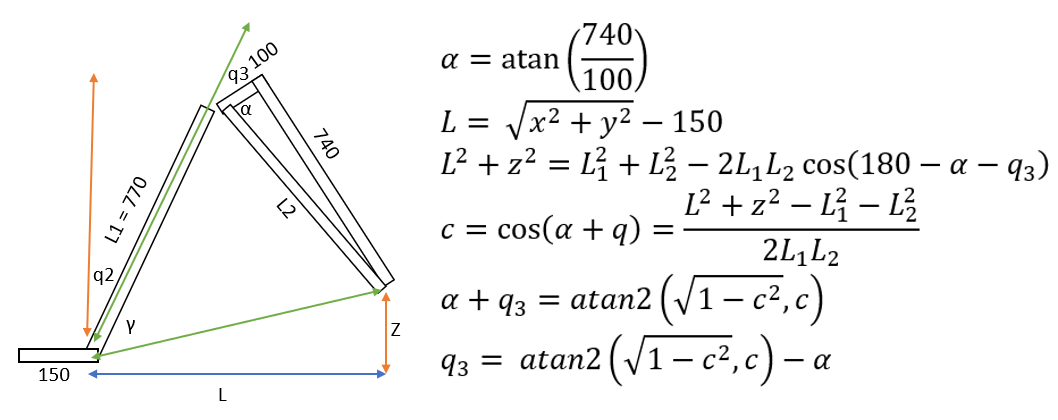

Para la articulación q2 es necesario aplicar la ley de senos para hallar el ángulo γ. Una vez hallado este ángulo es posible hallar q3.

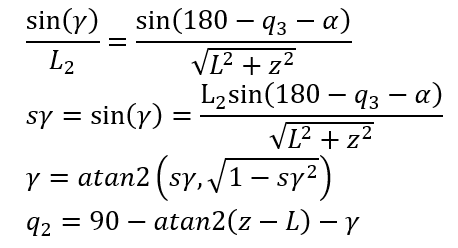

En cuanto a la orientación, es posible encontrar los ángulos $q_4,\ q_5\ y \ q_6$  despejando la matriz de orientación dada como si fuese una rotación YZY en el orden $q_4,\ q_5,\ q_6$. 

close all

Tej = transl(0.99, 0, 1.395)*troty(pi/2)*trotz(pi/2)

Tej =     0.0000   -0.0000    1.0000    0.9900
    1.0000    0.0000         0         0
   -0.0000    1.0000    0.0000    1.3950
         0         0         0    1.0000


[q1, q2, q3, q4, q5, q6] = myik([pi/4,0,0],[0.75,-0.661,0.961],Robot)

q1 = -0.6668

q2 = 0.1343

q3 = 0.3505

q4 = -0.9214

q5 = 0.7721

q6 = 1.4884

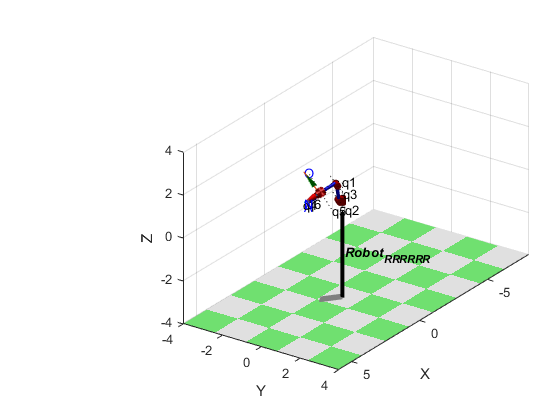

%Robot.teach([0 0 0 0 0 0])
Robot.teach([q1 q2 q3 q4 q5 q6]) 

2. En las soluciones de la inversa incluya consideraciones respecto a multiplicidad de soluciones. 

Se tuvo en cuenta la configuración de codo arriba en la articulación 3. Además de esto, es necesario tener en cuenta que el robot alcanza una configuración singular cada vez que q5 vale cero. Como consecuencia de esto, las ecuaciones obtenidas para la orientación resultan no solucionables debido a que se debe dividir por el seno de q5 para hallarlas, pero al dividir el valor entre cero la función retorna error. Otra diferentes configuraciones a solucionar son las de codo abajo y cuando q2 es lo suficientemente menor como para cambiar la posición x e y en 180º respecto a q1.

3. Haga uso de las funciones del RVC para hallar la cinemática inversa de su robot asignado y compruebe los resultados del punto anterior. Ya que existen varias funciones en el Toolbox explique: ¿Cuál es la diferencia entre estas funciones? ¿Cuál debe usar para su robot y por qué? (Revise la documentación del Toolbox ). 

close all
q = Robot.ikine(Tej)

q = 	1.0e+-15 *

    0.0008    0.0351   -0.3051   -0.0000    0.2701   -0.0000


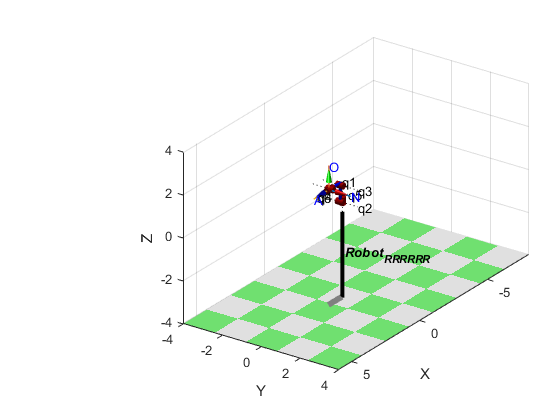

Robot.teach(q)

La mayoría de funciones del Toolbox retorna soluciones dependiendo del $q_0$ seleccionado inicialmente, que en la mayoría de los casos se considera como 0. Es por esto que las soluciones de las funciones ikcon no es recomendada para este robot. La función ikine3 está hecha para robots de 3 ejes sin muñeca, el cual no es el caso. Por esto, como el robot es de 6 GDL con muñeca esférica, se recomienda usar la función ikine6s. Sin embargo, solo funciona con parámetros de Denavit-Hartenberg estándar. Por esto se usó la función ikine.

4. Haga uso del RST para hallar la cinemática inversa de su robot asignado y compruebe los resultados anteriores. 

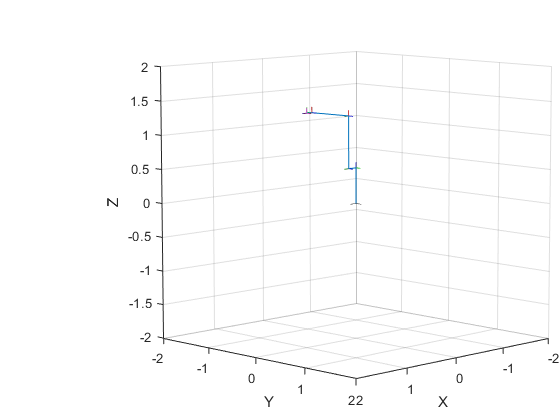

ik = inverseKinematics('RigidBodyTree',robot); weights = [0.25 0.25 0.25 1 1 1]; initialguess = robot.homeConfiguration;
[configSoln,solnInfo] = ik('body6',Tej,weights,initialguess);
show(robot,configSoln);

5. Compare los métodos. 

Teniendo en cuenta la posición inicial deseada y cada uno de los resultados, tanto en sintaxis como en presición el método del primer Toolbox fue más efectivo. No solo es más eficiente en el resultado encontrado, sino que también en velocidad. La función ikine usa un método que disminuye la divergencia de la solución mientras aumenta su convergencia. Es una solución bastante general pero no llega a ser tan eficiente como soluciones específicas (como ikine3 o ikine6, por ejemplo). A pesar de esto es mejor que la función del RST. 

6. Calcule la configuración del robot para las siguientes posturas de la herramienta. Proponga 4 posturas (x, y, z, roll, pitch, yaw) que esten dentro del espacio de trabajo y determine la configuración del manipulador y complete la tabla 2

[q1, q2, q3, q4, q5, q6] = myik([pi/4,0,0],[0.75,-0.661,0.961],Robot)

q1 = -0.6668

q2 = 0.1343

q3 = 0.3505

q4 = -0.9214

q5 = 0.7721

q6 = 1.4884

[q1, q2, q3, q4, q5, q6] = myik([pi/4,0,0],[1.0689,-0.661,0.961],Robot)

q1 = -0.5046

q2 = 0.4669

q3 = -0.0879

q4 = -0.8623

q5 = 0.9531

q6 = 1.5021

[q1, q2, q3, q4, q5, q6] = myik([pi/4,0,0],[1.072,-0.3390,0.6390],Robot)

q1 = -0.2452

q2 = 0.5234

q3 = 0.3129

q4 = -1.1031

q5 = 0.8765

q6 = 1.0084

[q1, q2, q3, q4, q5, q6] = myik([pi/4,0,0],[0.7531,-0.3390,0.6390],Robot)

q1 = -0.3422

q2 = 0.2149

q3 = 0.7828

q4 = -1.3013

q5 = 0.7629

q6 = 0.8317

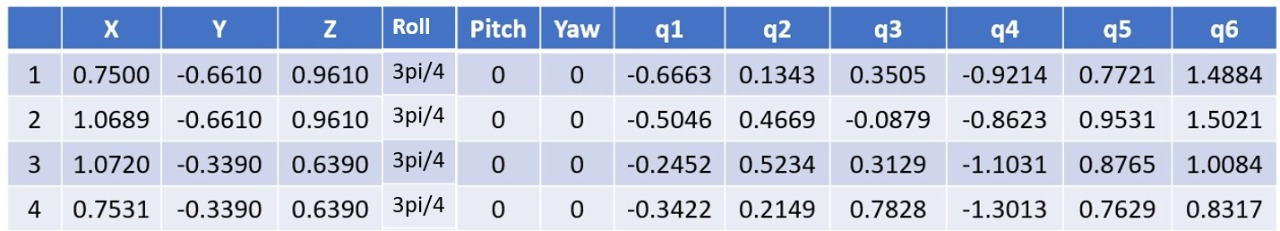

7. Haciendo uso de la GUI verifique que con la configuración calculada se obtiene la postura indicada de la herramienta. 

Se realiza la verificación con los puntos 1 y 2 del inciso anterior, en ambos casos se obtiene la postura indicada, cabe resaltar que el manejo de slides en la GUI dificulta ubicar los valores exactos en los que se debe encontrar cada articulación y por ello los valores de posición y orientación no son exactos, pero sí muy cercanos.

Punto 1.

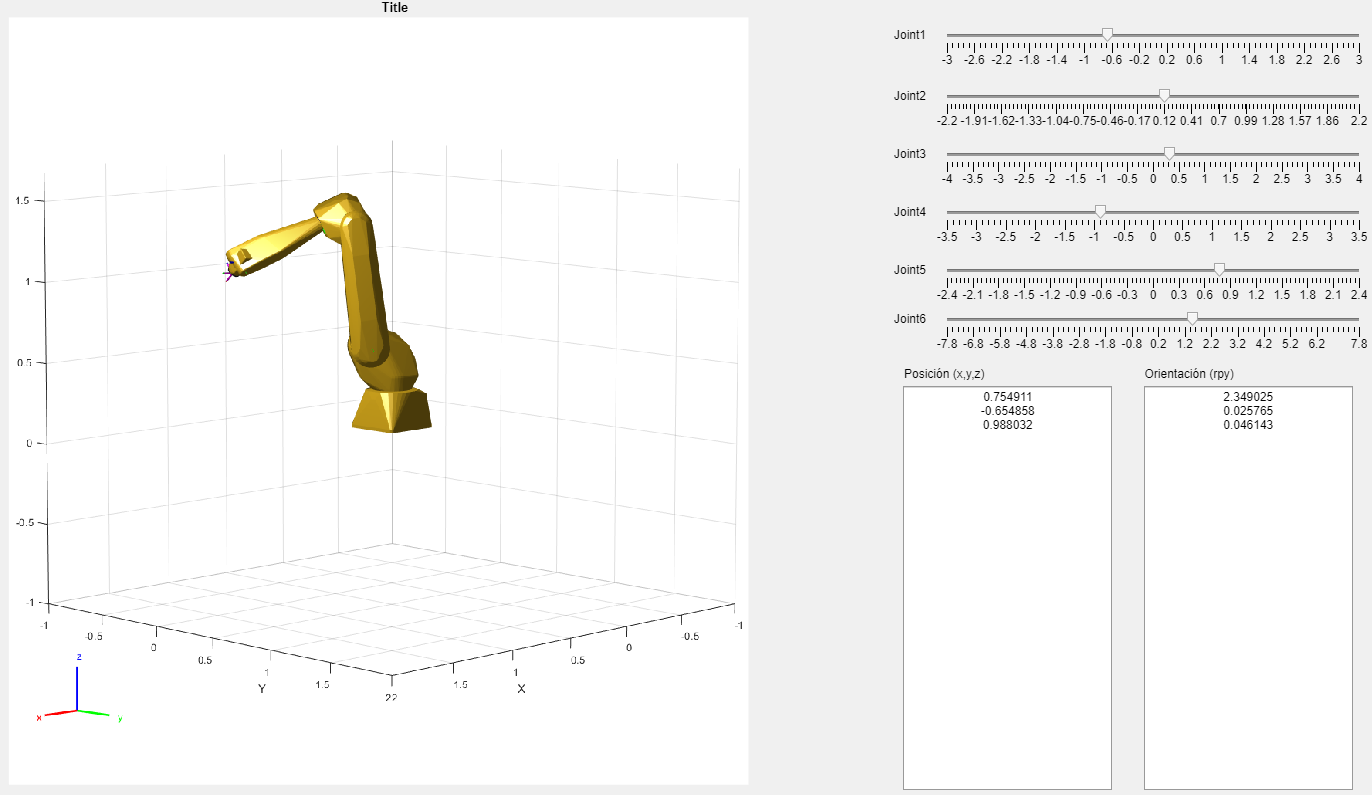

Punto 2.

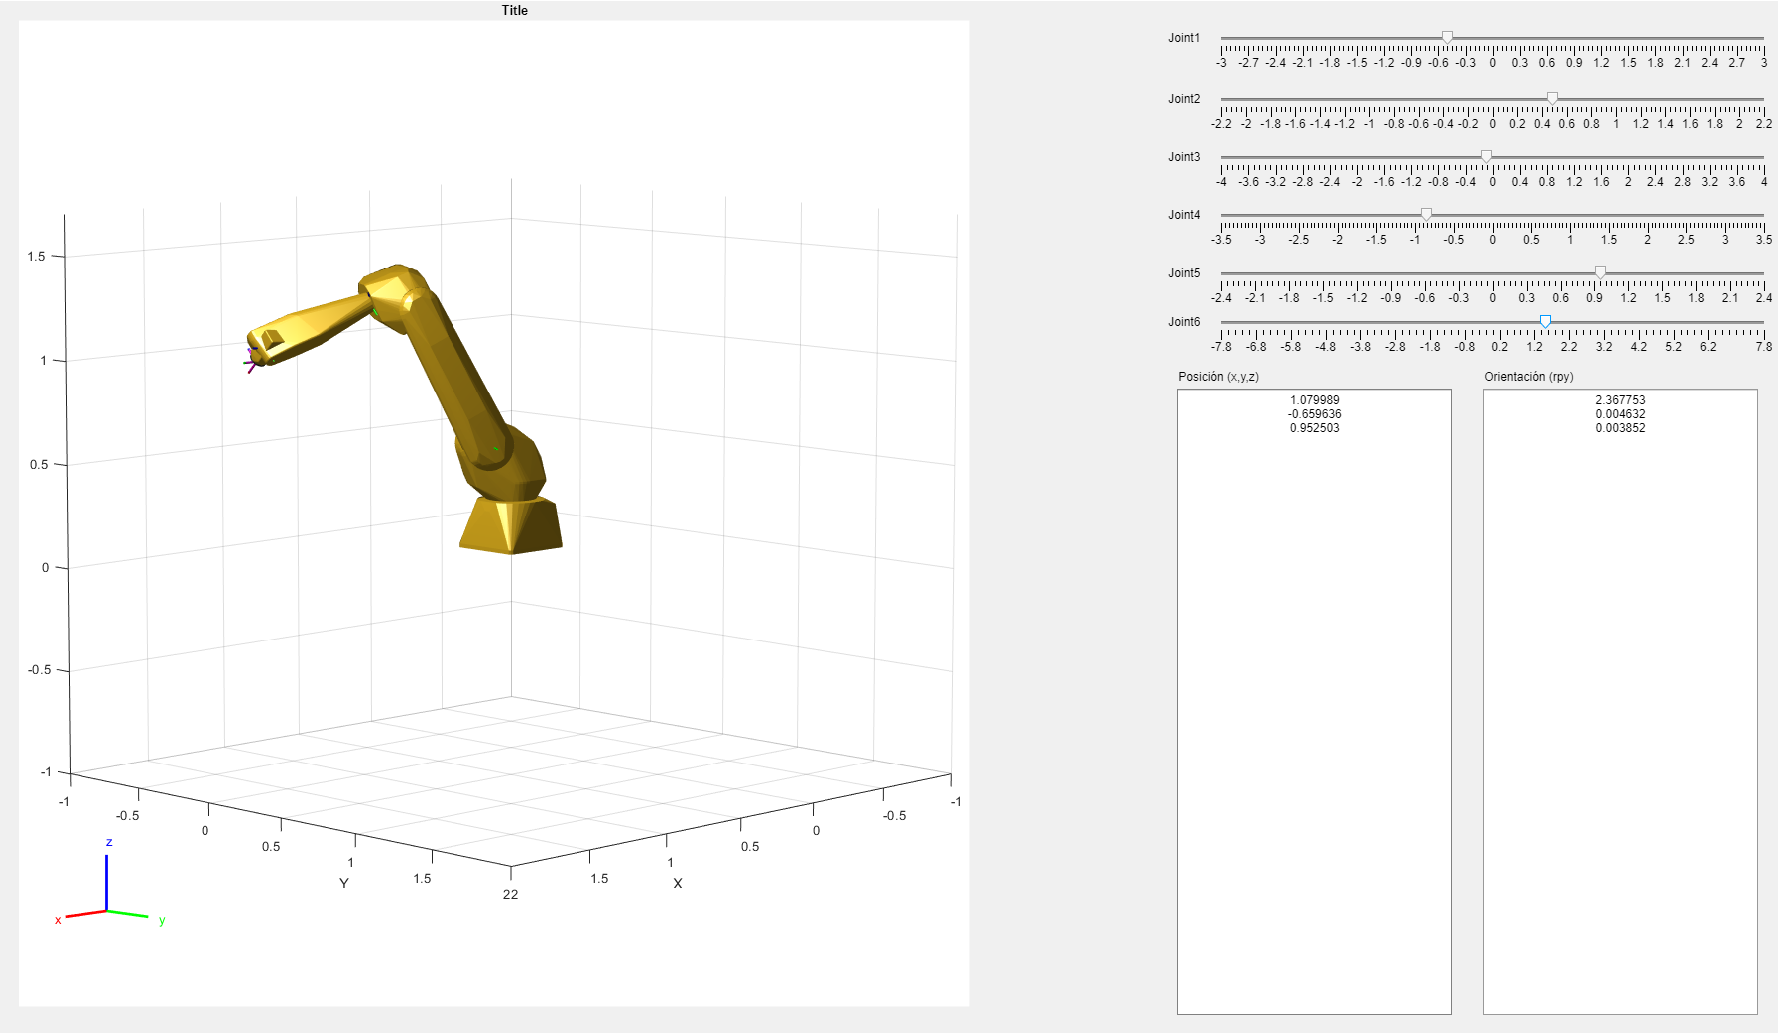

8. Para uno de los cuatro casos haga capturas de pantalla resaltando con cotas los valores x y z, e incluya en el informe los resultados.

Como muestra se utiliza la posición del punto 2 del inciso anterior.

Cota para la posición en X

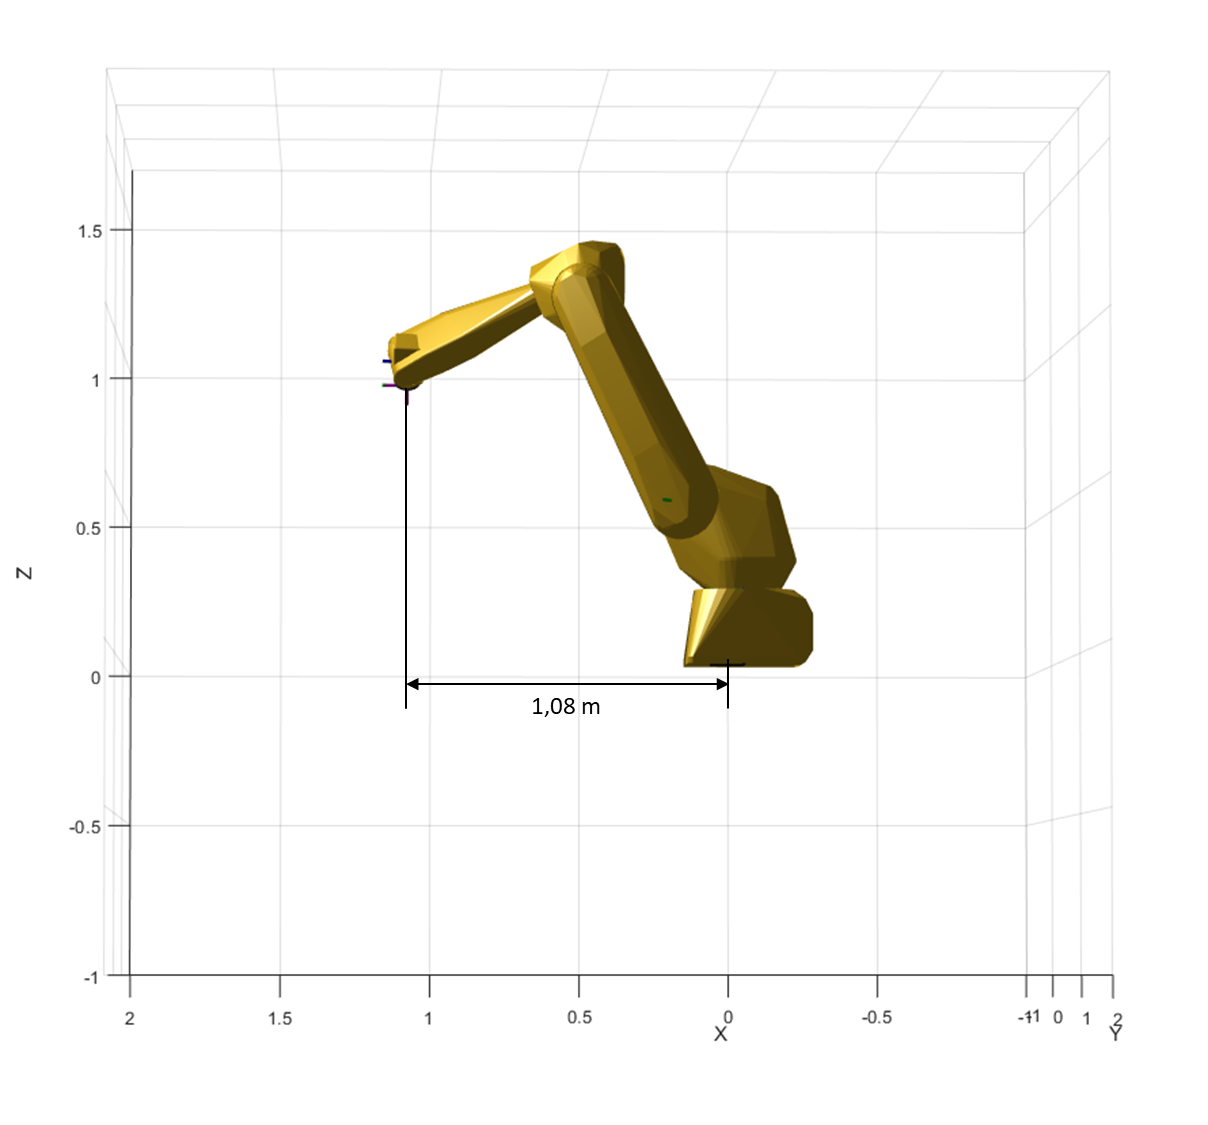

Cota para la posición en Y

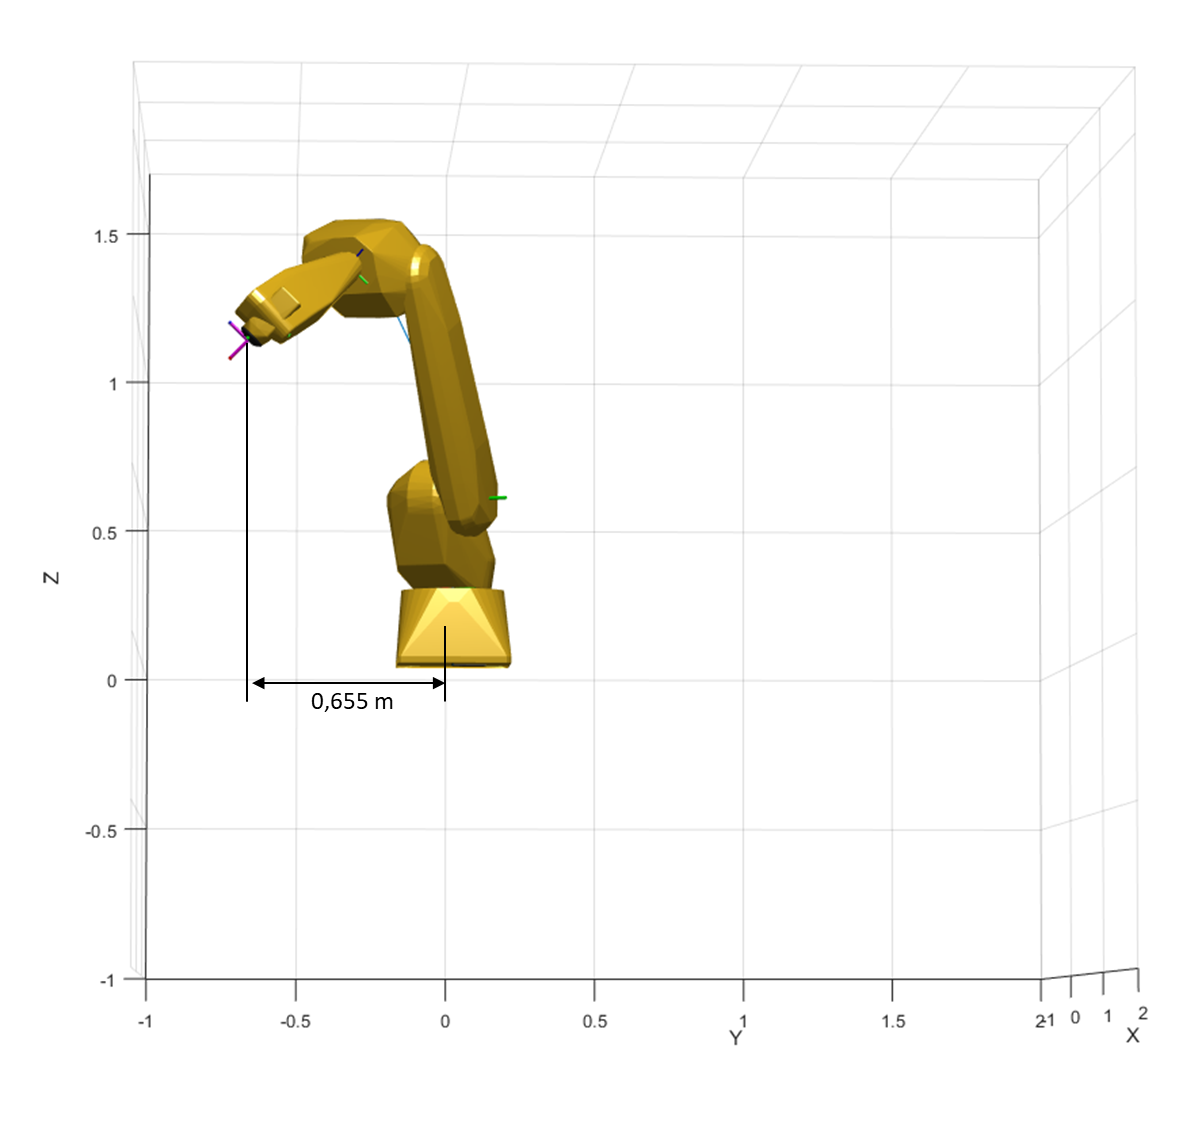

Cota para la posición en Z

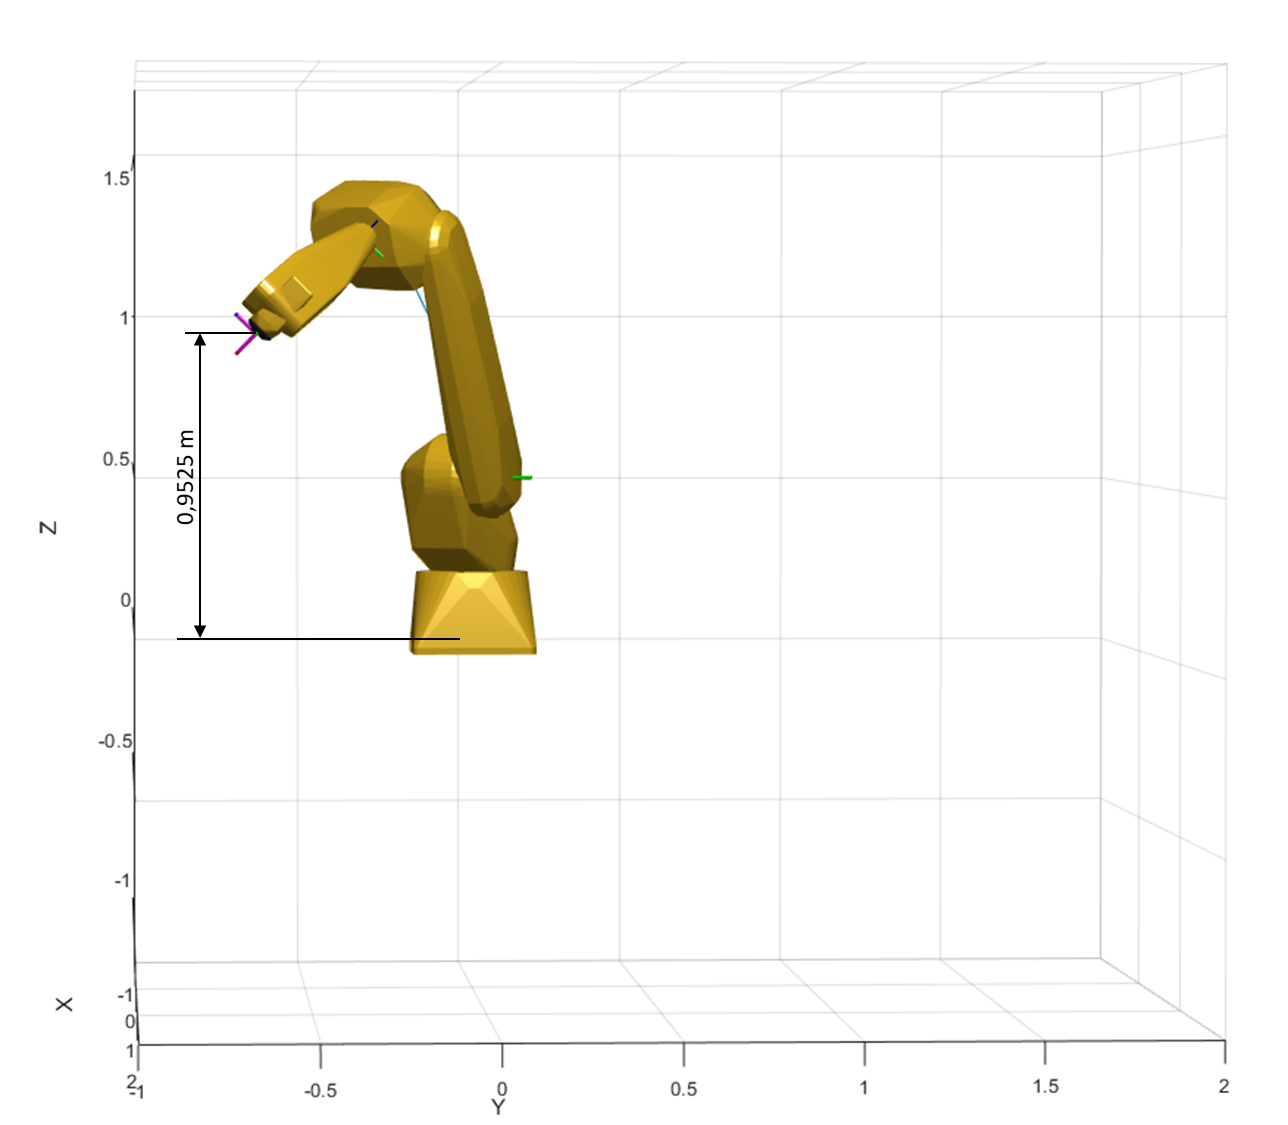

function [q1,q2,q3,q4,q5,q6] = myik(rpy, tras, SerialLink)
T = transl(tras)*rpy2tr(rpy);
dm = T(1:3,4)+0.1*T(1:3,2);
xm = dm(1);
ym = dm(2);
zm = dm(3)-0.525;
L = sqrt(xm^2+ym^2)-0.15;
L1 = 0.770;
L21 = 0.100;
L22 = 0.740;
L2 = sqrt(L21^2+L22^2);
q1 = atan2(ym, xm);
alpha = atan(0.740/0.100);
% Se trabajará codo arriba
ca3 = (L^2+zm^2-L1^2-L2^2)/(2*L1*L2);
q3a = atan2(sqrt(1-ca3^2),ca3);
q3 = q3a-alpha;
sg = L2*sin(pi-q3-alpha)/(sqrt(L^2+zm^2));
gamma = atan2(sg,sqrt(1-sg^2));
q2 = pi/2-atan2(zm,L)-gamma;
% Ya se tienen las primeras 3 matrices de rotación
T03 = trotz(q1)*troty(q2)*troty(q3);
R0_3 = SerialLink.A([1,2,3],[q1 -q2 -q3]);
R03 = R0_3(1:3,1:3);
R30 = R03';
R0f = T(1:3,1:3);
R3f = R30*R0f;
c5 = R3f(2,3);
q5 = atan2(sqrt(1-c5^2),c5);
s4 = R3f(3,3)/sin(q5);
q4 = atan2(s4,sqrt(1-s4^2));
s6 = R3f(2,1)/sin(q5);
q6 = atan2(s6,sqrt(1-s6^2));

end